# Tema 4 - PRÁCTICA OPTATIVA

# Identificación de dígitos

## Enunciado

Realizar programa que admita como entrada una imagen de la carpeta 'Barcode' y como salida marque, sobre la propia imagen, los dígitos detectados asignando un color diferente a cada número.

Para ello deberá definir, en primer lugar, una variable que contenta todas las posibles plantillas a buscar en la imagen y sus correspondientes umbrales de detección.

NOTA: La carpeta Barcode se encuentra en el archivo de imágenes accesibles desde la primera pestaña del campus virtual.

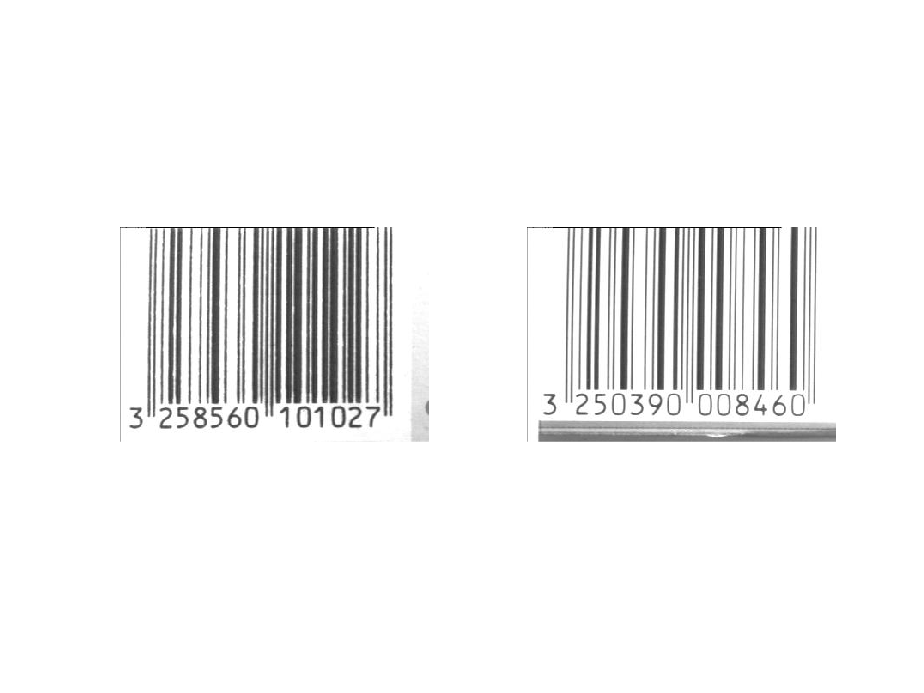

clear
im0 = imread("../Imagenes/Barcode/Image00.jpg");
im1 = imread("../Imagenes/Barcode/Image01.jpg");
figure;
subplot(1,2,1); imshow(im0);
subplot(1,2,2); imshow(im1);

### plantillas.mat

Plantillas de números para las imágenes de códigos de barrasArchivo

Carga una variable llamada 'plantillas' que contiene una estructura de datos con las 10 plantillas a buscar. Tiene un campo 'im' en el que se almacena la plantilla correspondiente al índice que se especifique.

Ejemplo para visualizar la plantilla del número 5:

    >> imshow(plantilla(5).im))

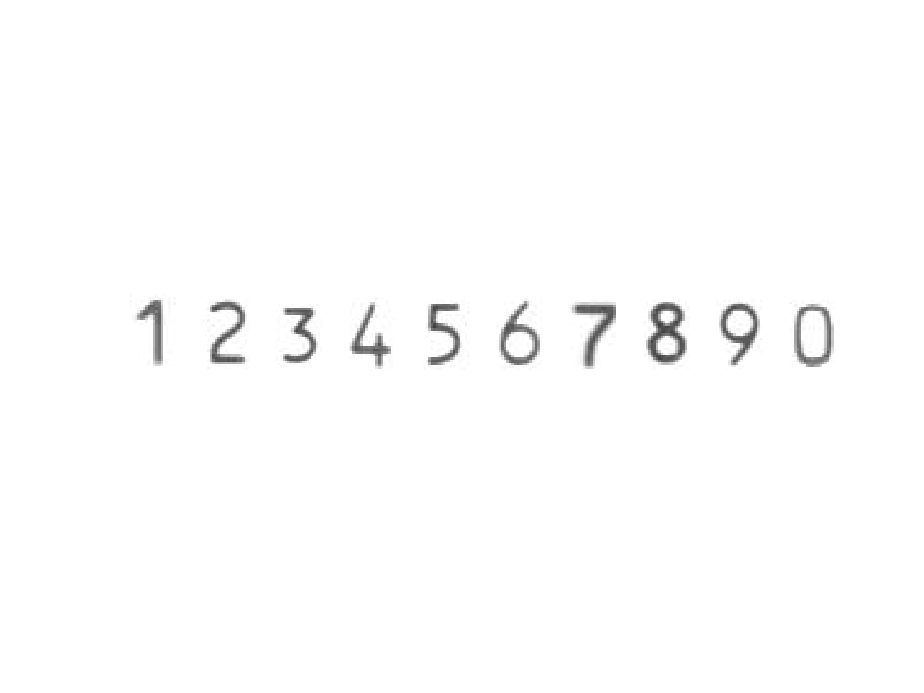

load('plantillas.mat');
figure;
for i=1:10
    subplot(1,10,i);
    imshow(plantillas(i).im);
end

## Solución

### 1 Base del algoritmo

Para identificar los números se utiliza correlación normalizada entre la plantilla de cada uno de los dígitos y la imagen de entrada:

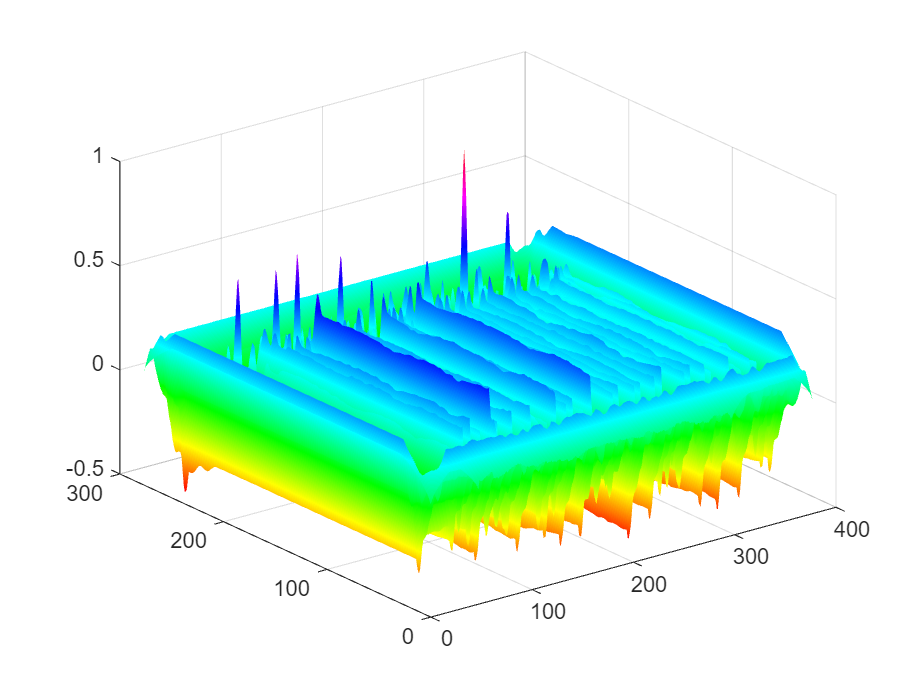

img = im1; % imagen de entrada
np = 8; % número de plantilla
imc = normxcorr2(plantillas(np).im, img);
figure; surf(double(imc)); shading interp; colormap hsv;

Una vez sabemos donde hay mayor correlación, superponemos a la imagen del código de barras los pixeles por encima del umbral

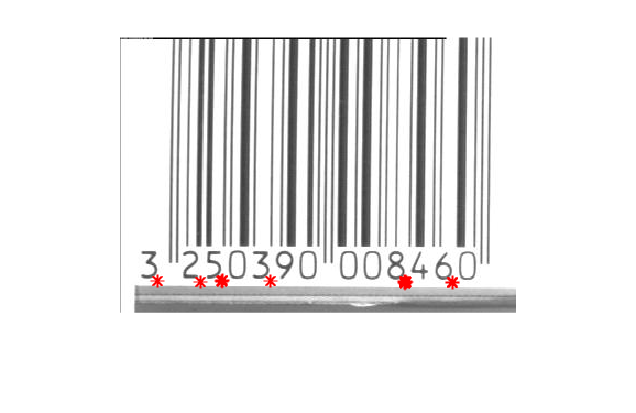

umbrales = [0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5];
[x, y] = find(imc > umbrales(np));
figure; imshow(img); hold on; plot(y, x, '*', color='red');

### 2 Ajuste del umbral para el dígito 1

Obseramos que, con un umbral de 0.5, la plantilla del 8 también identifica dígitos que se parecen (2, 3, 5, 6).

Repetimos la prueba para el caso del dígito 1, que es el que puede dar más problemas:

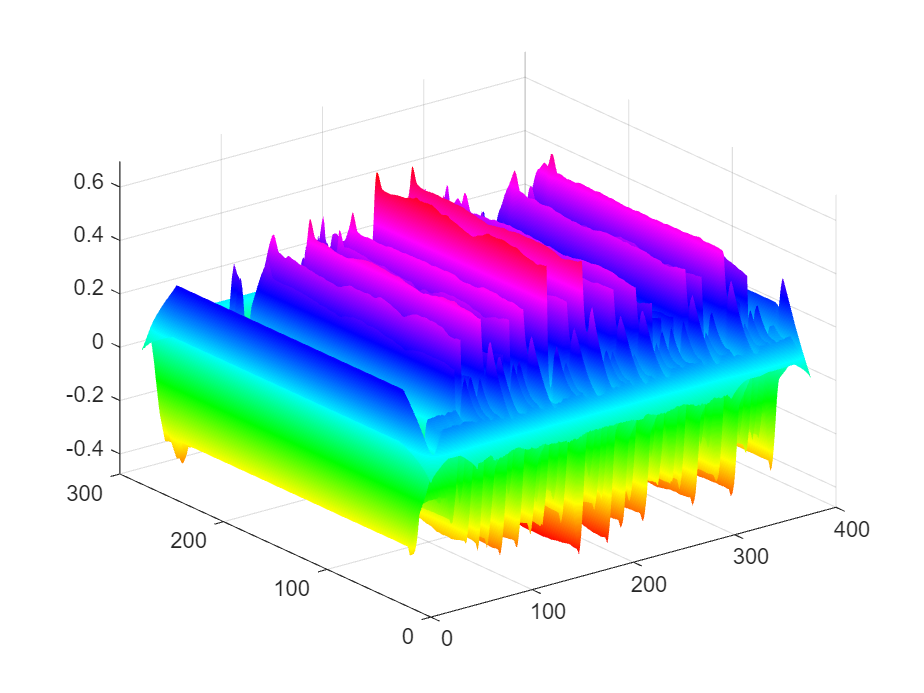

np = 1; % número de plantilla
imc = normxcorr2(plantillas(np).im, img);
figure; surf(double(imc)); shading interp; colormap hsv;

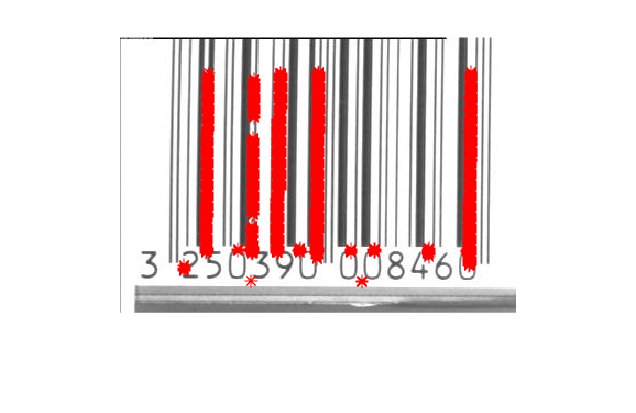

umbrales = [0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5];
[x, y] = find(imc > umbrales(np));
figure; imshow(img); hold on; plot(y, x, '*', color='red');

El umbral para el dígito 1 es demasiado laxo y todas las barras verticales se confunden con el dígito, que ni siquiera está en la imagen. 

Bajamos el umbral para el dígito 1 y lo probamos con una imagen en la que aparezca (imagen 2).

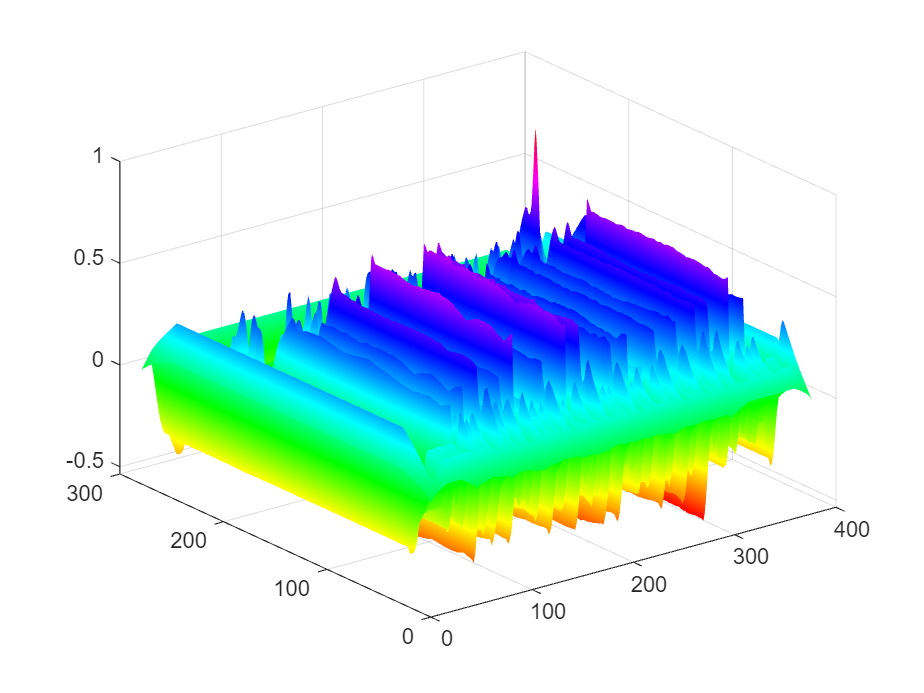

ni = 2; % en la imagen 02 el dígito 1 aparece
np = 1; % número de plantilla de dígito

img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
imc = normxcorr2(plantillas(np).im, img);

figure; surf(double(imc)); shading interp; colormap hsv;

Utilizamos ensayo y error para modificar el umbral del dígito 1 hasta que identique el dígito y no las barras verticales.

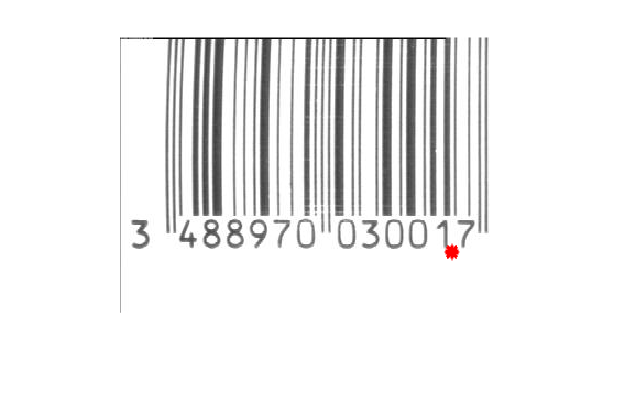

umbrales = [0.8 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5 0.5];
[x, y] = find(imc > umbrales(np));
figure; imshow(img); hold on; plot(y, x, '*', 'Color', 'red');

### 3 Umbrales para cada dígito

Repetimos el proceso anterior con cada uno de los dígitos:

- Subimos todos los umbrales para que sólo se detecten los dígitos en los que hemos ajustado el umbral

- Metemos la correlación en un for para iterar con cada uno de los dígitos

- Aprovechamos para definir una paleta de colores que nos permita distinguirlos visualmente

#### Dígito 1 (versión bucle for)

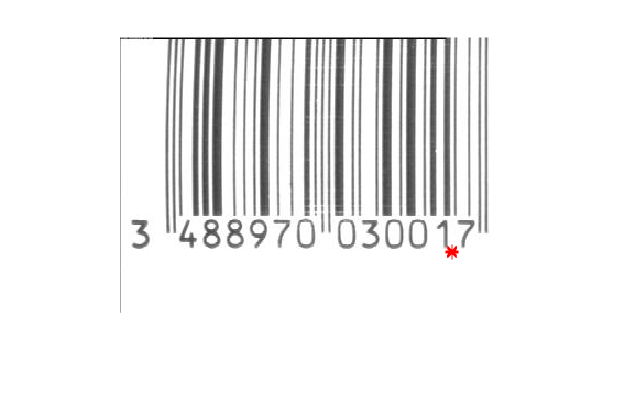

umbrales = [0.9 1.1 1.1 1.1 1.1 1.1 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 2; % en la imagen 02 el dígito 1 aparece
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 2 (fichero Image01)

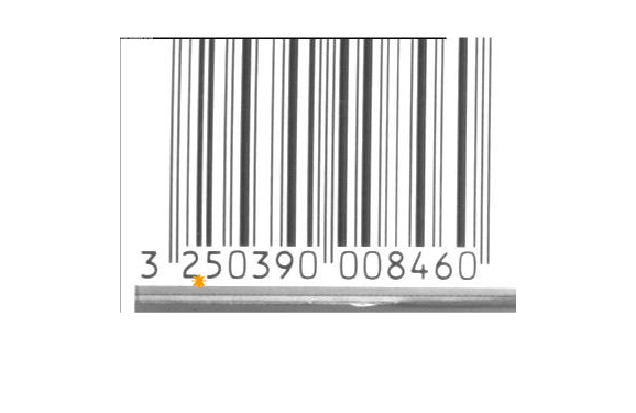

umbrales = [0.9 0.8 1.1 1.1 1.1 1.1 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 1; % en la imagen 01 el dígito 2 aparece
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 3 (fichero Image01)

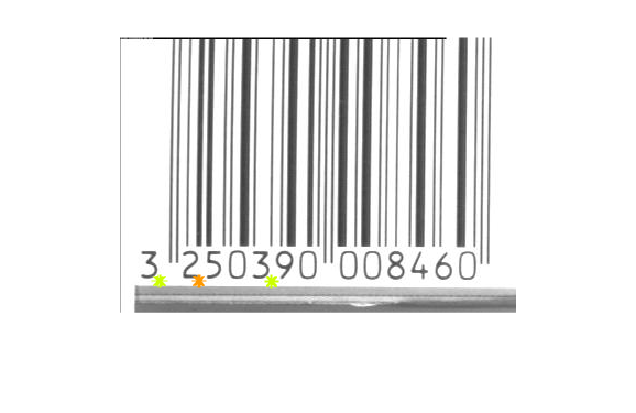

umbrales = [0.9 0.8 0.8 1.1 1.1 1.1 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 1; % en la imagen 01 el dígito 2 aparece
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 4 (fichero Image02)

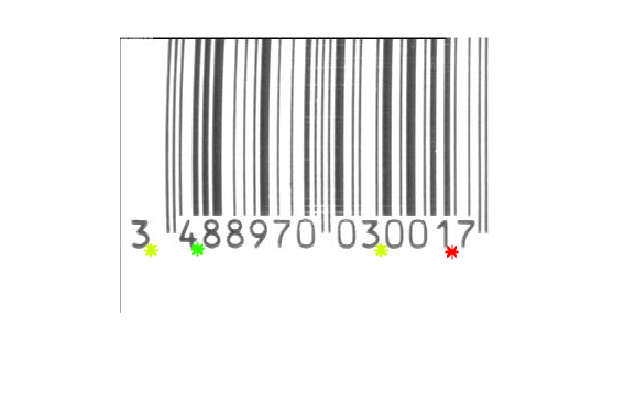

umbrales = [0.9 0.8 0.8 0.8 1.1 1.1 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 2; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 5 (fichero Image03)

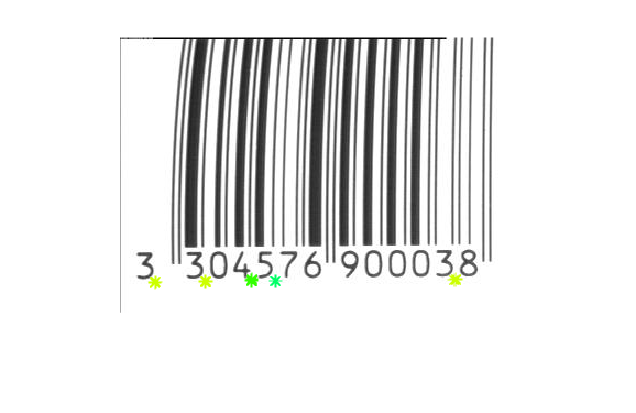

umbrales = [0.9 0.8 0.8 0.8 0.8 1.1 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 3; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 6 (fichero Image03)

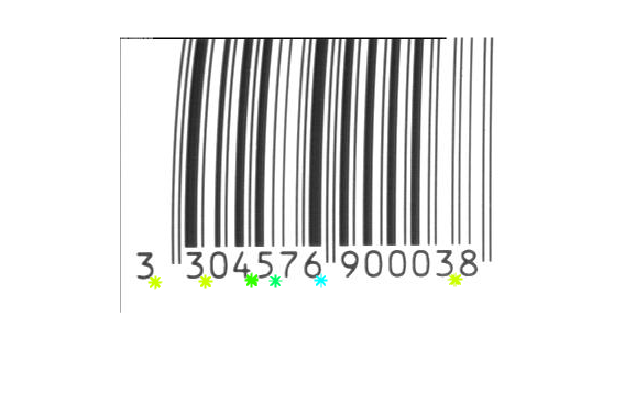

umbrales = [0.9 0.8 0.8 0.8 0.8 0.8 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 3; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 7 (fichero Image04)

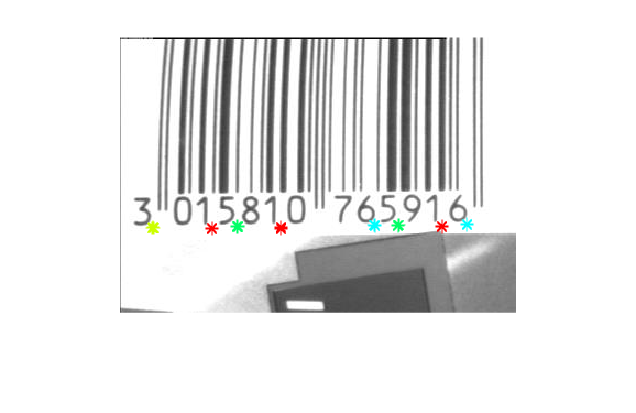

umbrales = [0.9 0.8 0.8 0.8 0.8 0.85 1.1 1.1 1.1 1.1];
colores = hsv(10);

ni = 4; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 7 (fichero Image03)

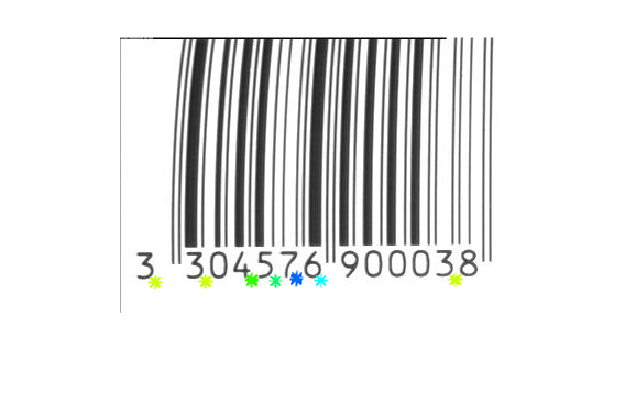

umbrales = [0.9 0.8 0.8 0.8 0.8 0.85 0.8 1.1 1.1 1.1];
colores = hsv(10);

ni = 3; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 8 (fichero Image03)

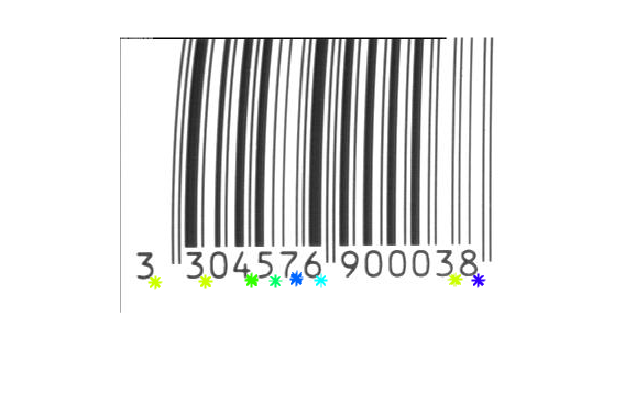

umbrales = [0.9 0.8 0.8 0.8 0.8 0.85 0.8 0.8 1.1 1.1];
colores = hsv(10);

ni = 3; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 9 (fichero Image03)

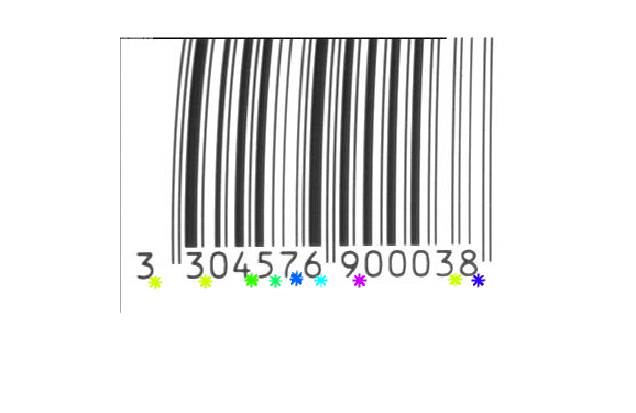

umbrales = [0.9 0.8 0.8 0.8 0.8 0.85 0.8 0.8 0.8 1.1];
colores = hsv(10);

ni = 3; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

#### Dígito 0 (fichero Image03)

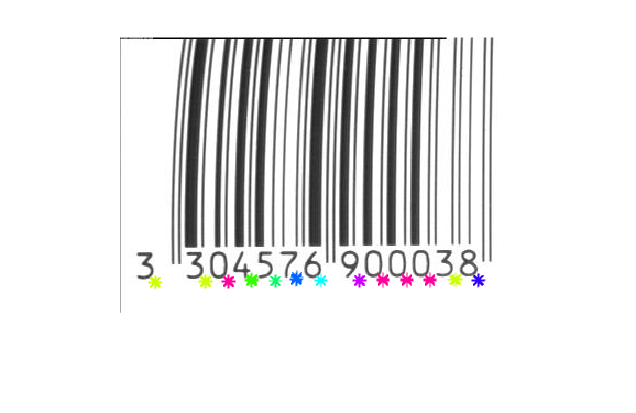

umbrales = [0.9 0.8 0.8 0.8 0.8 0.85 0.8 0.8 0.8 0.70];
colores = hsv(10);

ni = 3; 
img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
figure; imshow(img); hold on;

for np = 1:10 % para cada dígito del 1 al 0
    imc = normxcorr2(plantillas(np).im, img);
    [x, y] = find(imc > umbrales(np));
    plot(y, x, '*', 'Color', colores(np, :));
end

### Prueba con todas las imágenes

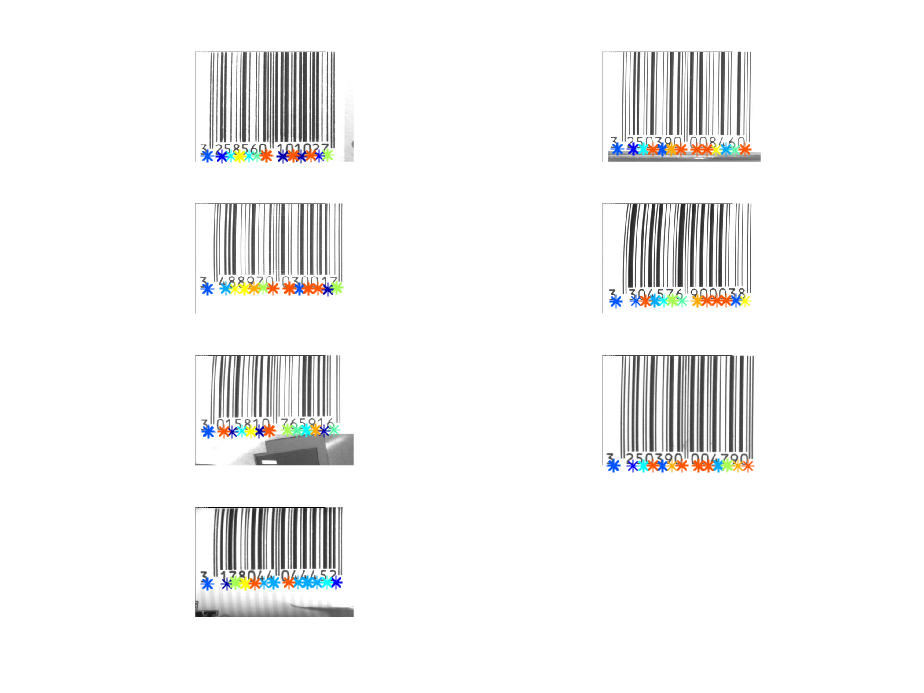

umbrales = [0.9 0.8 0.8 0.8 0.8 0.85 0.8 0.8 0.8 0.70];
colores = jet(10); %hsv(10);

figure
for ni = 0:6
    img = imread(sprintf("../Imagenes/Barcode/Image%02d.jpg", ni));
    subplot(4,2,ni+1); imshow(img); hold on;

    for np = 1:10 % para cada dígito del 1 al 0
        imc = normxcorr2(plantillas(np).im, img);
        [x, y] = find(imc > umbrales(np));
        plot(y, x, '*', 'Color', colores(np, :));
        %colorbar
    end
end

## Programa empaquetado

### Prueba de funcionamiento

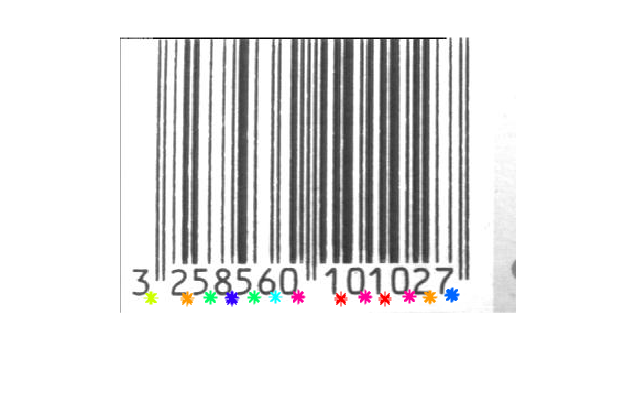

im0 = imread("../Imagenes/Barcode/Image00.jpg");
MarcarDigitos(im0);